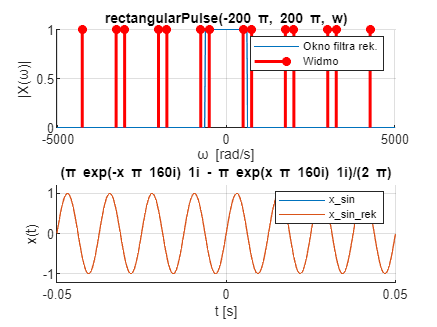

clear all; 
close all;
syms t x w K

fp = 200; 
fg = fp/2; %Hz
wp = 2*pi*fp; 
wg = 2*pi*fg;

s = 4/5; 
ws = s*wg;

x_sin = sin(ws*t);
X_FT_sin_org = fourier(x_sin);

X_FT_sin = X_FT_sin_org + ... % oryginal widma
    symsum((subs(X_FT_sin_org, w, w - K*wp ) + ...% 3 aliasy lewe
    subs(X_FT_sin_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe

FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy
x_sin_rek = ifourier(X_FT_sin*FILT_FT); % odwr. tarnsf. Fouriera

BND_t = [-10/fp;10/fp];
%t_SMP = [BND_t(1):1/(10*fp):BND_t(2) ];
BND_w = [-4*wp;4*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2)];

figure; subplot(2,1,1); hold on; grid on;
ezplot(FILT_FT,BND_w); %okno filtru rek.
%ezplot(X_FT_sin,BND_w)

v_num = abs(double(subs(X_FT_sin, w, w_SMP)));
n = find(abs(v_num) == Inf);
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');


subplot(2,1,2); hold on; grid on;
ezplot(x_sin, BND_t); % syg. próbkowany
ezplot(x_sin_rek, BND_t) % syg. odtworzony
xlabel('t [s]'); ylabel('x(t)')
legend('x\_sin','x\_sin\_rek');

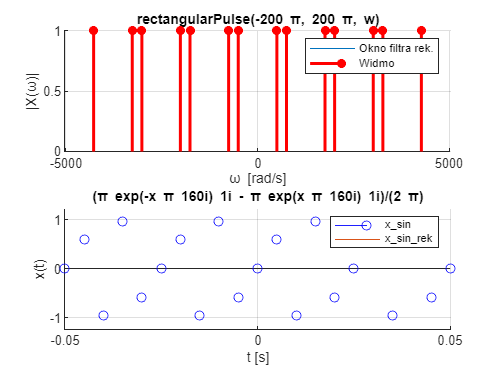

% Zadanie 2
x_sin = sin(ws*t);
X_FT_sin_org = fourier(x_sin);

X_FT_sin = X_FT_sin_org + ... % oryginal widma
    symsum((subs(X_FT_sin_org, w, w - K*wp ) + ...% 3 aliasy lewe
    subs(X_FT_sin_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe

FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy
x_sin_rek = ifourier(X_FT_sin*FILT_FT); % odwr. tarnsf. Fouriera

BND_t = [-10/fp;10/fp];
%t_SMP = [BND_t(1):1/(10*fp):BND_t(2) ];
BND_w = [-4*wp;4*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2)];

figure; subplot(2,1,1); hold on; grid on;
ezplot(FILT_FT,BND_w); %okno filtru rek.
%ezplot(X_FT_sin,BND_w)

v_num = abs(double(subs(X_FT_sin, w, w_SMP)));
n = find(abs(v_num) == Inf);
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');

wezly = BND_t(1) : 1/fp : BND_t(2);
wezly_val = subs(x_sin_rek, x, wezly);

subplot(2,1,2); hold on; grid on;
stem(wezly, wezly_val, 'b');
ezplot(x_sin, BND_t); % syg. próbkowany
ezplot(x_sin_rek, BND_t) % syg. odtworzony
xlabel('t [s]'); ylabel('x(t)')
legend('x\_sin','x\_sin\_rek');

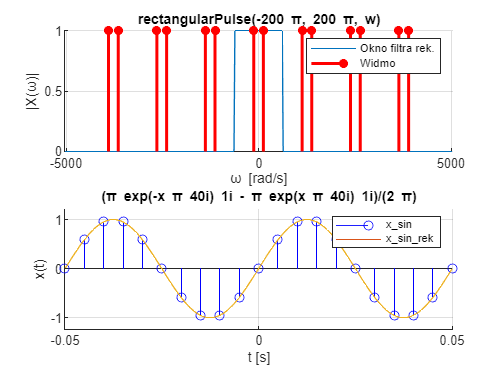

% Zadanie  3
% a)
s = 1/5; 
ws = s*wg;

x_sin = sin(ws*t);
X_FT_sin_org = fourier(x_sin);

X_FT_sin = X_FT_sin_org + ... % oryginal widma
    symsum((subs(X_FT_sin_org, w, w - K*wp ) + ...% 3 aliasy lewe
    subs(X_FT_sin_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe

FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy
x_sin_rek = ifourier(X_FT_sin*FILT_FT); % odwr. tarnsf. Fouriera

BND_t = [-10/fp;10/fp];
%t_SMP = [BND_t(1):1/(10*fp):BND_t(2) ];
BND_w = [-4*wp;4*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2)];

figure; subplot(2,1,1); hold on; grid on;
ezplot(FILT_FT,BND_w); %okno filtru rek.
%ezplot(X_FT_sin,BND_w)

v_num = abs(double(subs(X_FT_sin, w, w_SMP)));
n = find(abs(v_num) == Inf);
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');

wezly = BND_t(1) : 1/fp : BND_t(2);
wezly_val = subs(x_sin_rek, x, wezly);

subplot(2,1,2); hold on; grid on;
stem(wezly, wezly_val, 'b');
ezplot(x_sin, BND_t); % syg. próbkowany
ezplot(x_sin_rek, BND_t) % syg. odtworzony
xlabel('t [s]'); ylabel('x(t)')
legend('x\_sin','x\_sin\_rek');

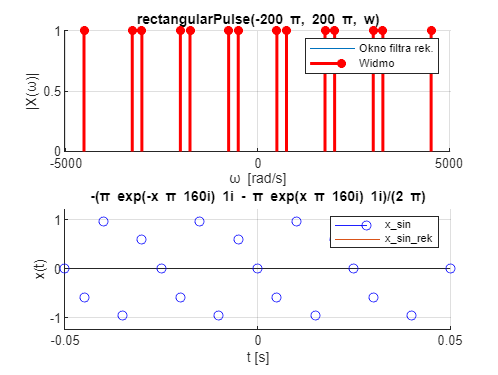

% Zadanie 3
% b)
s = 6/5; 
ws = s*wg;

x_sin = sin(ws*t);
X_FT_sin_org = fourier(x_sin);

X_FT_sin = X_FT_sin_org + ... % oryginal widma
    symsum((subs(X_FT_sin_org, w, w - K*wp ) + ...% 3 aliasy lewe
    subs(X_FT_sin_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe

FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy
x_sin_rek = ifourier(X_FT_sin*FILT_FT); % odwr. tarnsf. Fouriera

BND_t = [-10/fp;10/fp];
%t_SMP = [BND_t(1):1/(10*fp):BND_t(2) ];
BND_w = [-4*wp;4*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2)];

figure; subplot(2,1,1); hold on; grid on;
ezplot(FILT_FT,BND_w); %okno filtru rek.
%ezplot(X_FT_sin,BND_w)

v_num = abs(double(subs(X_FT_sin, w, w_SMP)));
n = find(abs(v_num) == Inf);
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');

wezly = BND_t(1) : 1/fp : BND_t(2);
wezly_val = subs(x_sin_rek, x, wezly);

subplot(2,1,2); hold on; grid on;
stem(wezly, wezly_val, 'b');
ezplot(x_sin, BND_t); % syg. próbkowany
ezplot(x_sin_rek, BND_t) % syg. odtworzony
xlabel('t [s]'); ylabel('x(t)')
legend('x\_sin','x\_sin\_rek');

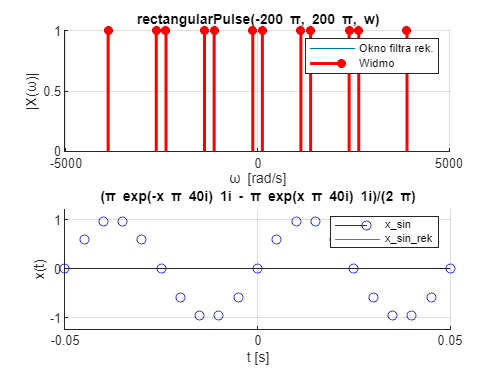

% Zadanie 3
% c)
s = 11/5; 
ws = s*wg;

x_sin = sin(ws*t);
X_FT_sin_org = fourier(x_sin);

X_FT_sin = X_FT_sin_org + ... % oryginal widma
    symsum((subs(X_FT_sin_org, w, w - K*wp ) + ...% 3 aliasy lewe
    subs(X_FT_sin_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe

FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy
x_sin_rek = ifourier(X_FT_sin*FILT_FT); % odwr. tarnsf. Fouriera

BND_t = [-10/fp;10/fp];
%t_SMP = [BND_t(1):1/(10*fp):BND_t(2) ];
BND_w = [-4*wp;4*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2)];

figure; subplot(2,1,1); hold on; grid on;
ezplot(FILT_FT,BND_w); %okno filtru rek.
%ezplot(X_FT_sin,BND_w)

v_num = abs(double(subs(X_FT_sin, w, w_SMP)));
n = find(abs(v_num) == Inf);
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');

wezly = BND_t(1) : 1/fp : BND_t(2);
wezly_val = subs(x_sin_rek, x, wezly);

subplot(2,1,2); hold on; grid on;
stem(wezly, wezly_val, 'b');
ezplot(x_sin, BND_t); % syg. próbkowany
ezplot(x_sin_rek, BND_t) % syg. odtworzony
xlabel('t [s]'); ylabel('x(t)')
legend('x\_sin','x\_sin\_rek');

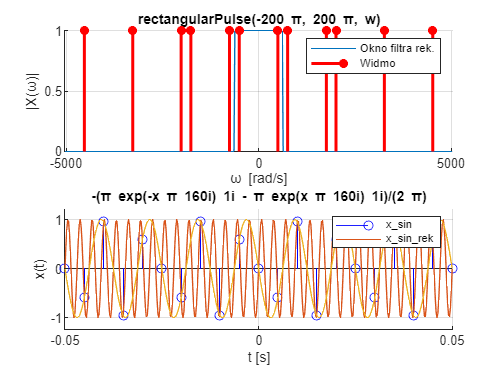

% Zadanie 3
% d)
s = 16/5; 
ws = s*wg;

x_sin = sin(ws*t);
X_FT_sin_org = fourier(x_sin);

X_FT_sin = X_FT_sin_org + ... % oryginal widma
    symsum((subs(X_FT_sin_org, w, w - K*wp ) + ...% 3 aliasy lewe
    subs(X_FT_sin_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe

FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy
x_sin_rek = ifourier(X_FT_sin*FILT_FT); % odwr. tarnsf. Fouriera

BND_t = [-10/fp;10/fp];
%t_SMP = [BND_t(1):1/(10*fp):BND_t(2) ];
BND_w = [-4*wp;4*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2)];

figure; subplot(2,1,1); hold on; grid on;
ezplot(FILT_FT,BND_w); %okno filtru rek.
%ezplot(X_FT_sin,BND_w)

v_num = abs(double(subs(X_FT_sin, w, w_SMP)));
n = find(abs(v_num) == Inf);
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');

wezly = BND_t(1) : 1/fp : BND_t(2);
wezly_val = subs(x_sin_rek, x, wezly);

subplot(2,1,2); hold on; grid on;
stem(wezly, wezly_val, 'b');
ezplot(x_sin, BND_t); % syg. próbkowany
ezplot(x_sin_rek, BND_t) % syg. odtworzony
xlabel('t [s]'); ylabel('x(t)')
legend('x\_sin','x\_sin\_rek');

% Zadanie 3
% e)
s = 4/5; 
ws = s*wg;

x_sin = sin(ws*t);
X_FT_sin_org = fourier(x_sin);

X_FT_sin = X_FT_sin_org + ... % oryginal widma
    symsum((subs(X_FT_sin_org, w, w - K*wp ) + ...% 3 aliasy lewe
    subs(X_FT_sin_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe

FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy
x_sin_rek = ifourier(X_FT_sin*FILT_FT); % odwr. tarnsf. Fouriera

BND_t = [-10/fp;10/fp];
%t_SMP = [BND_t(1):1/(10*fp):BND_t(2) ];
BND_w = [-4*wp;4*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2)];

figure; subplot(2,1,1); hold on; grid on;
ezplot(FILT_FT,BND_w); %okno filtru rek.
%ezplot(X_FT_sin,BND_w)

v_num = abs(double(subs(X_FT_sin, w, w_SMP)));
n = find(abs(v_num) == Inf);
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');

wezly = BND_t(1) : 1/fp : BND_t(2);
wezly_val = subs(x_sin_rek, x, wezly);

subplot(2,1,2); hold on; grid on;
stem(wezly, wezly_val, 'b');
ezplot(x_sin, BND_t); % syg. próbkowany
ezplot(x_sin_rek, BND_t) % syg. odtworzony
xlabel('t [s]'); ylabel('x(t)')
legend('x\_sin','x\_sin\_rek');

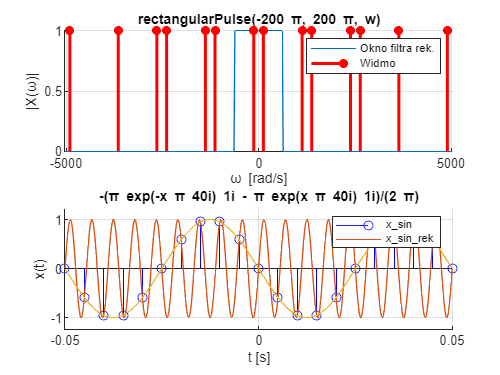

% Zadanie 3
% f)
s = 9/5; 
ws = s*wg;

x_sin = sin(ws*t);
X_FT_sin_org = fourier(x_sin);

X_FT_sin = X_FT_sin_org + ... % oryginal widma
    symsum((subs(X_FT_sin_org, w, w - K*wp ) + ...% 3 aliasy lewe
    subs(X_FT_sin_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe

FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy
x_sin_rek = ifourier(X_FT_sin*FILT_FT); % odwr. tarnsf. Fouriera

BND_t = [-10/fp;10/fp];
%t_SMP = [BND_t(1):1/(10*fp):BND_t(2) ];
BND_w = [-4*wp;4*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2)];

figure; subplot(2,1,1); hold on; grid on;
ezplot(FILT_FT,BND_w); %okno filtru rek.
%ezplot(X_FT_sin,BND_w)

v_num = abs(double(subs(X_FT_sin, w, w_SMP)));
n = find(abs(v_num) == Inf);
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');

wezly = BND_t(1) : 1/fp : BND_t(2);
wezly_val = subs(x_sin_rek, x, wezly);

subplot(2,1,2); hold on; grid on;
stem(wezly, wezly_val, 'b');
ezplot(x_sin, BND_t); % syg. próbkowany
ezplot(x_sin_rek, BND_t) % syg. odtworzony
xlabel('t [s]'); ylabel('x(t)')
legend('x\_sin','x\_sin\_rek');

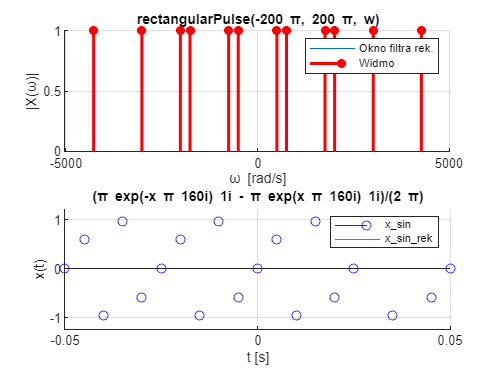

% Zadanie 3
% g)
s = 14/5; 
ws = s*wg;

x_sin = sin(ws*t);
X_FT_sin_org = fourier(x_sin);

X_FT_sin = X_FT_sin_org + ... % oryginal widma
    symsum((subs(X_FT_sin_org, w, w - K*wp ) + ...% 3 aliasy lewe
    subs(X_FT_sin_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe

FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy
x_sin_rek = ifourier(X_FT_sin*FILT_FT); % odwr. tarnsf. Fouriera

BND_t = [-10/fp;10/fp];
%t_SMP = [BND_t(1):1/(10*fp):BND_t(2) ];
BND_w = [-4*wp;4*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2)];

figure; subplot(2,1,1); hold on; grid on;
ezplot(FILT_FT,BND_w); %okno filtru rek.
%ezplot(X_FT_sin,BND_w)

v_num = abs(double(subs(X_FT_sin, w, w_SMP)));
n = find(abs(v_num) == Inf);
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');

wezly = BND_t(1) : 1/fp : BND_t(2);
wezly_val = subs(x_sin_rek, x, wezly);

subplot(2,1,2); hold on; grid on;
stem(wezly, wezly_val, 'b');
ezplot(x_sin, BND_t); % syg. próbkowany
ezplot(x_sin_rek, BND_t) % syg. odtworzony
xlabel('t [s]'); ylabel('x(t)')
legend('x\_sin','x\_sin\_rek');

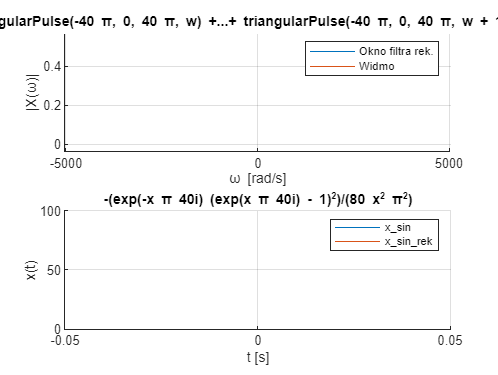

% zadanie 4
%a)
fp = 200; 
fg = fp/2; %Hz
wp = 2*pi*fp; 
wg = 2*pi*fg;

s = 1/5; 
ws = s*wg;

x_sin = ifourier(triangularPulse(-ws, ws, w));
X_FT_sin_org = triangularPulse(-ws, ws, w);

X_FT_sin = X_FT_sin_org + ... % oryginal widma
    symsum((subs(X_FT_sin_org, w, w - K*wp ) + ...% 3 aliasy lewe
    subs(X_FT_sin_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe

FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy
x_sin_rek = ifourier(X_FT_sin*FILT_FT); % odwr. tarnsf. Fouriera

BND_t = [-10/fp;10/fp];
%t_SMP = [BND_t(1):1/(10*fp):BND_t(2) ];
BND_w = [-4*wp;4*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2)];

figure; subplot(2,1,1); hold on; grid on;
ezplot(FILT_FT,BND_w); %okno filtru rek.
ezplot(X_FT_sin,BND_w)

v_num = abs(double(subs(X_FT_sin, w, w_SMP)));
n = find(abs(v_num) == Inf);
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');

subplot(2,1,2); hold on; grid on;
ezplot(x_sin, BND_t); % syg. próbkowany
ezplot(x_sin_rek, BND_t) % syg. odtworzony
ylim([0 100])
xlabel('t [s]'); ylabel('x(t)')
legend('x\_sin','x\_sin\_rek');

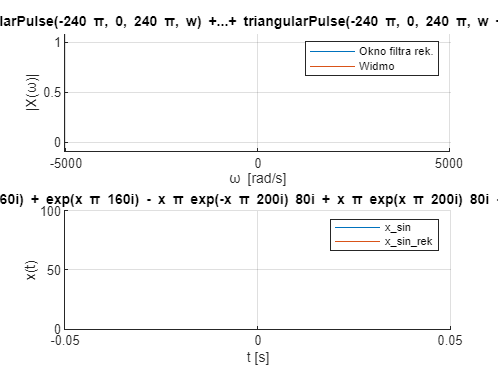

% Zadanie 4
%b)
s = 6/5; 
ws = s*wg;

x_sin = ifourier(triangularPulse(-ws, ws, w));
X_FT_sin_org = triangularPulse(-ws, ws, w);

X_FT_sin = X_FT_sin_org + ... % oryginal widma
    symsum((subs(X_FT_sin_org, w, w - K*wp ) + ...% 3 aliasy lewe
    subs(X_FT_sin_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe

FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy
x_sin_rek = ifourier(X_FT_sin*FILT_FT); % odwr. tarnsf. Fouriera

BND_t = [-10/fp;10/fp];
%t_SMP = [BND_t(1):1/(10*fp):BND_t(2) ];
BND_w = [-4*wp;4*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2)];

figure; subplot(2,1,1); hold on; grid on;
ezplot(FILT_FT,BND_w); %okno filtru rek.
ezplot(X_FT_sin,BND_w)

v_num = abs(double(subs(X_FT_sin, w, w_SMP)));
n = find(abs(v_num) == Inf);
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');

subplot(2,1,2); hold on; grid on;
ezplot(x_sin, BND_t); % syg. próbkowany
ezplot(x_sin_rek, BND_t) % syg. odtworzony
ylim([0 100])
xlabel('t [s]'); ylabel('x(t)')
legend('x\_sin','x\_sin\_rek');

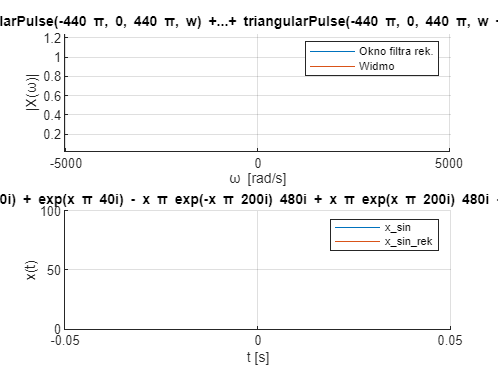

% Zadanie 4
%c)
s = 11/5; 
ws = s*wg;

x_sin = ifourier(triangularPulse(-ws, ws, w));
X_FT_sin_org = triangularPulse(-ws, ws, w);

X_FT_sin = X_FT_sin_org + ... % oryginal widma
    symsum((subs(X_FT_sin_org, w, w - K*wp ) + ...% 3 aliasy lewe
    subs(X_FT_sin_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe

FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy
x_sin_rek = ifourier(X_FT_sin*FILT_FT); % odwr. tarnsf. Fouriera

BND_t = [-10/fp;10/fp];
%t_SMP = [BND_t(1):1/(10*fp):BND_t(2) ];
BND_w = [-4*wp;4*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2)];

figure; subplot(2,1,1); hold on; grid on;
ezplot(FILT_FT,BND_w); %okno filtru rek.
ezplot(X_FT_sin,BND_w)

v_num = abs(double(subs(X_FT_sin, w, w_SMP)));
n = find(abs(v_num) == Inf);
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');

subplot(2,1,2); hold on; grid on;
ezplot(x_sin, BND_t); % syg. próbkowany
ezplot(x_sin_rek, BND_t) % syg. odtworzony
ylim([0 100])
xlabel('t [s]'); ylabel('x(t)')
legend('x\_sin','x\_sin\_rek');

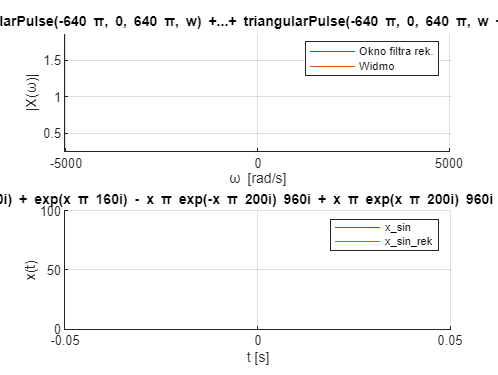

% Zadanie 4
%d)
s = 16/5; 
ws = s*wg;

x_sin = ifourier(triangularPulse(-ws, ws, w));
X_FT_sin_org = triangularPulse(-ws, ws, w);

X_FT_sin = X_FT_sin_org + ... % oryginal widma
    symsum((subs(X_FT_sin_org, w, w - K*wp ) + ...% 3 aliasy lewe
    subs(X_FT_sin_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe

FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy
x_sin_rek = ifourier(X_FT_sin*FILT_FT); % odwr. tarnsf. Fouriera

BND_t = [-10/fp;10/fp];
%t_SMP = [BND_t(1):1/(10*fp):BND_t(2) ];
BND_w = [-4*wp;4*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2)];

figure; subplot(2,1,1); hold on; grid on;
ezplot(FILT_FT,BND_w); %okno filtru rek.
ezplot(X_FT_sin,BND_w)

v_num = abs(double(subs(X_FT_sin, w, w_SMP)));
n = find(abs(v_num) == Inf);
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');

subplot(2,1,2); hold on; grid on;
ezplot(x_sin, BND_t); % syg. próbkowany
ezplot(x_sin_rek, BND_t) % syg. odtworzony
ylim([0 100])
xlabel('t [s]'); ylabel('x(t)')
legend('x\_sin','x\_sin\_rek');

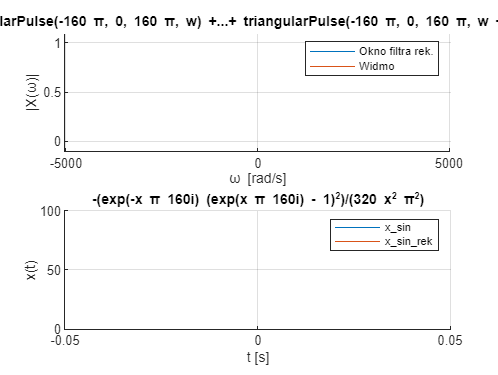

% Zadanie 4
%e)
s = 4/5; 
ws = s*wg;

x_sin = ifourier(triangularPulse(-ws, ws, w));
X_FT_sin_org = triangularPulse(-ws, ws, w);

X_FT_sin = X_FT_sin_org + ... % oryginal widma
    symsum((subs(X_FT_sin_org, w, w - K*wp ) + ...% 3 aliasy lewe
    subs(X_FT_sin_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe

FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy
x_sin_rek = ifourier(X_FT_sin*FILT_FT); % odwr. tarnsf. Fouriera

BND_t = [-10/fp;10/fp];
%t_SMP = [BND_t(1):1/(10*fp):BND_t(2) ];
BND_w = [-4*wp;4*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2)];

figure; subplot(2,1,1); hold on; grid on;
ezplot(FILT_FT,BND_w); %okno filtru rek.
ezplot(X_FT_sin,BND_w)

v_num = abs(double(subs(X_FT_sin, w, w_SMP)));
n = find(abs(v_num) == Inf);
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');

subplot(2,1,2); hold on; grid on;
ezplot(x_sin, BND_t); % syg. próbkowany
ezplot(x_sin_rek, BND_t) % syg. odtworzony
ylim([0 100])
xlabel('t [s]'); ylabel('x(t)')
legend('x\_sin','x\_sin\_rek');

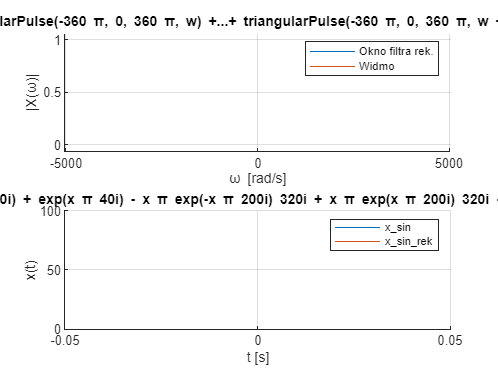

% Zadanie 4
%f)
s = 9/5; 
ws = s*wg;

x_sin = ifourier(triangularPulse(-ws, ws, w));
X_FT_sin_org = triangularPulse(-ws, ws, w);

X_FT_sin = X_FT_sin_org + ... % oryginal widma
    symsum((subs(X_FT_sin_org, w, w - K*wp ) + ...% 3 aliasy lewe
    subs(X_FT_sin_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe

FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy
x_sin_rek = ifourier(X_FT_sin*FILT_FT); % odwr. tarnsf. Fouriera

BND_t = [-10/fp;10/fp];
%t_SMP = [BND_t(1):1/(10*fp):BND_t(2) ];
BND_w = [-4*wp;4*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2)];

figure; subplot(2,1,1); hold on; grid on;
ezplot(FILT_FT,BND_w); %okno filtru rek.
ezplot(X_FT_sin,BND_w)

v_num = abs(double(subs(X_FT_sin, w, w_SMP)));
n = find(abs(v_num) == Inf);
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');

subplot(2,1,2); hold on; grid on;
ezplot(x_sin, BND_t); % syg. próbkowany
ezplot(x_sin_rek, BND_t) % syg. odtworzony
ylim([0 100])
xlabel('t [s]'); ylabel('x(t)')
legend('x\_sin','x\_sin\_rek');

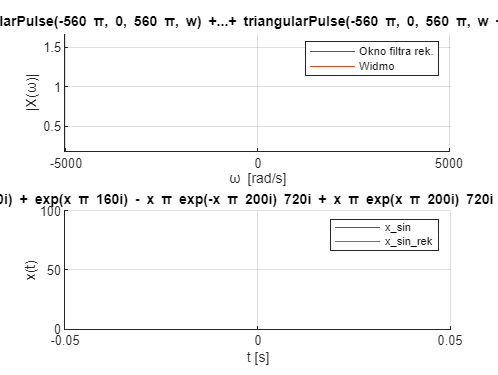

% Zadanie 4
%g)
s = 14/5; 
ws = s*wg;

x_sin = ifourier(triangularPulse(-ws, ws, w));
X_FT_sin_org = triangularPulse(-ws, ws, w);

X_FT_sin = X_FT_sin_org + ... % oryginal widma
    symsum((subs(X_FT_sin_org, w, w - K*wp ) + ...% 3 aliasy lewe
    subs(X_FT_sin_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe

FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy
x_sin_rek = ifourier(X_FT_sin*FILT_FT); % odwr. tarnsf. Fouriera

BND_t = [-10/fp;10/fp];
%t_SMP = [BND_t(1):1/(10*fp):BND_t(2) ];
BND_w = [-4*wp;4*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2)];

figure; subplot(2,1,1); hold on; grid on;
ezplot(FILT_FT,BND_w); %okno filtru rek.
ezplot(X_FT_sin,BND_w)

v_num = abs(double(subs(X_FT_sin, w, w_SMP)));
n = find(abs(v_num) == Inf);
stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');

subplot(2,1,2); hold on; grid on;
ezplot(x_sin, BND_t); % syg. próbkowany
ezplot(x_sin_rek, BND_t) % syg. odtworzony
ylim([0 100])
xlabel('t [s]'); ylabel('x(t)')
legend('x\_sin','x\_sin\_rek');

% Zadanie 5
clear all;
syms t x w K;
fp = 200;
fg = fp/2;
wp = 2*pi*fp;
wg = 2*pi*fg;
s = 1/5; 
ws = s*wg;
fs = s * fg;
T = 1/fs;

% oryginalny przebieg prostokątny
x = rectangularPulse(0, t/2, t);
% Kod generujący wyrazy szeregu Fouriera
NT = 50;
sumX = 0;
ind=-NT:NT;
BND = [-T/2, T/2];
for n = ind
    Xn = 1/T*int(x*exp(-1i*ws*n*t),t,BND);
    % Wzór (8) z konspektu.
    % Tworzy X(jw) ze współczynników Xn
    sumX = sumX + Xn * dirac(w - n*ws);
end
X_FT_org = 2*pi * sumX;

FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy
x_ft_rek = ifourier(X_FT_org*FILT_FT); % odwr. tarnsf. Fouriera

BND_t = [-10/fp;10/fp];
t_SMP = [BND_t(1):1/(10*fp):BND_t(2) ];
BND_w = [-3*wp;3*wp];
w_SMP = [BND_w(1):wp/10:BND_w(2)];

figure; subplot(2,1,1); hold on; grid on;
ezplot(FILT_FT,BND_w); %okno filtru rek.
ezplot(X_FT_org,BND_w)

Error using inlineeval (line 13)
Error in inline expression ==> 2.*pi.*(20.*dirac(w - 40.*pi).*int(exp(-t.*pi.*40i).*rectangularPulse(0, t./2, t), t, -1./40, 1./40) + 20.*dirac(w + 40.*pi).*int(exp(t.*pi.*40i).*rectangularPulse(0, t./2, t), t, -1./40, 1./40) + 20.*dirac(w - 80.*pi).*int(exp(-t.*pi.*80i).*rectangularPulse(0, t./2, t), t, -1./40, 1./40) + 20.*dirac(w + 80.*pi).*int(exp(t.*pi.*80i).*rectangularPulse(0, t./2, t), t, -1./40, 1./40) + 20.*dirac(w - 120.*pi).*int(exp(-t.*pi.*120i).*rectangularPulse(0, t./2, t), t, -1./40, 1./40) + 20.*dirac(w + 120.*pi).*int(exp(t.*pi.*120i).*rectangularPulse(0, t./2, t), t, -1./40, 1./40) + 20.*dirac(w - 160.*pi).*int(exp(-t.*pi.*160i).*rectangularPul


v_num = subs(imag(X_FT_org), w, w_SMP);
n = find(abs(v_num) == Inf);
stem(w_SMP(n),abs(sign(v_num(n))),'r*', 'LineWidth', 2);
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');

v_num = subs(real(X_FT_org), w, w_SMP);
n = find(abs(v_num) == Inf);
stem(w_SMP(n),abs(sign(v_num(n))),'r*', 'LineWidth', 2);

subplot(2,1,2); hold on; grid on;
ezplot(fourier(X_FT_org), BND_t); % syg. próbkowany
ezplot(x_ft_rek, BND_t) % syg. odtworzony
ylim([0 100])
xlabel('t [s]'); ylabel('x(t)')
legend('x\_sin','x\_sin\_rek');